clc; clear; close all;

%% ================================================================
%  LQR TEST - VOLTAGE INPUT VERSION
%  Rotary Inverted Pendulum
%
%  Original model:
%       x_dot = A_tau*x + B_tau*tau_m
%
%  New model:
%       x_dot = A_volt*x + B_volt*V_m
%
%  State vector:
%       x = [theta_1;
%            theta_2;
%            dtheta_1;
%            dtheta_2]
%
%  Input:
%       V_m = motor voltage [V]
%% ================================================================


%% 1. Original torque-based model

A_tau = [0 0 1 0;
         0 0 0 1;
         0 16.5917 0 0;
         0 105.5970 0 0];

B_tau = [0;
         0;
         1475.6369;
         1173.3223];


%% 2. Motor parameters

%% Motor parameters (QUBE-Servo 3)
% Datasheet for Qube-Servo 3 has almost no direct values for the motor
% parameters - these parameters are mostly estimation and assumptions

Rm = 8.4;        % [Ohm] Motor terminal resistance
kt = 0.042;      % [N*m/A] Motor torque constant
km = 0.042;      % [V*s/rad] Back-EMF constant

Kg = 1;          % Direct-drive, no gearbox - If not direct drive, change value to "70"

eta_m = 1;       % Assumed ideal motor efficiency
eta_g = 1;       % No gearbox, so gear efficiency = 1

% Voltage-to-torque gain:
%
% tau_m = alpha*V_m - beta*dtheta_1

alpha = eta_g*Kg*eta_m*kt/Rm;

% Back-EMF damping term:
%
% This term reduces motor torque when the motor is already spinning.

beta = eta_g*Kg^2*eta_m*kt*km/Rm;


%% 3. Convert model from torque input to voltage input

A_volt = A_tau;
B_volt = B_tau * alpha;

% Since tau_m contains -beta*dtheta_1,
% this becomes an extra damping term in the A matrix.
%
% dtheta_1 is state x3, so we modify column 3.

A_volt(:,3) = A_volt(:,3) - B_tau*beta;


%% 4. Display converted matrices

disp("A_volt = ");

A_volt = 


disp(A_volt);

         0         0    1.0000         0
         0         0         0    1.0000
         0   16.5917   -0.3099         0
         0  105.5970   -0.2464         0




disp("B_volt = ");

B_volt = 


disp(B_volt);

         0
         0
    7.3782
    5.8666





%% 5. State-space setup

C = eye(4);
D = zeros(4,1);

sys_open = ss(A_volt, B_volt, C, D);


%% 6. Open-loop poles

disp("Open-loop poles with voltage model:");

Open-loop poles with voltage model:


p_open = eig(A_volt)

p_open =          0
   10.2572
  -10.2959
   -0.2711




%% 7. Check controllability

Co = ctrb(A_volt, B_volt);
rank_Co = rank(Co);
n = size(A_volt,1);

disp("Controllability rank:");

Controllability rank:


disp(rank_Co);

     4




if rank_Co == n
    disp("System is controllable.");
else
    warning("System is NOT fully controllable.");
end

System is controllable.




%% 8. LQR tuning

% LQR minimizes:
%
% J = integral( x'Qx + V_m'R*V_m ) dt
%
% Now R penalizes voltage use, not torque use.

Q = diag([10, 500, 1, 50]);

% Since voltage is usually limited, R should not be too small.
% Smaller R = more aggressive voltage command.
% Larger R  = softer voltage command.

R = 1;


%% 9. Calculate LQR gain

K = lqr(A_volt, B_volt, Q, R);

disp("Voltage-based LQR gain K:");

Voltage-based LQR gain K:


disp(K);

   -3.1623   99.2422   -2.3708   12.0973




% Control law:
%
% V_m = -K*x

Acl = A_volt - B_volt*K;

disp("Closed-loop poles:");

Closed-loop poles:


p_closed = eig(Acl)

p_closed =  -44.3499 + 0.0000i
  -3.4803 + 0.0000i
  -2.9790 + 2.2570i
  -2.9790 - 2.2570i




%% 10. Stability check

if all(real(p_closed) < 0)
    disp("Closed-loop system is stable.");
else
    warning("Closed-loop system is NOT stable.");
end

Closed-loop system is stable.


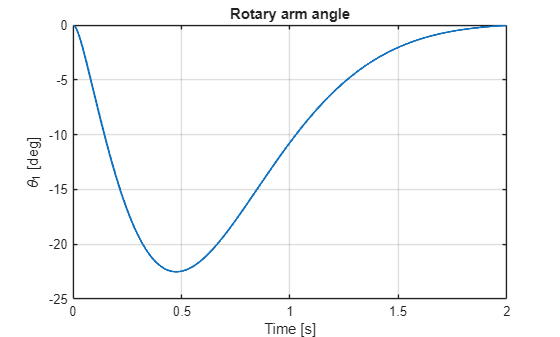



%% 11. Simulate initial condition response

deg = pi/180;

% Example:
% Pendulum starts 5 degrees away from upright.

x0 = [0;
      5*deg;
      0;
      0];

t = 0:0.001:2;

sys_cl = ss(Acl, B_volt, C, D);

[y,t,x] = initial(sys_cl, x0, t);


%% 12. Calculate voltage command

V = zeros(length(t),1);

for i = 1:length(t)
    V(i) = -K*x(i,:)';
end


%% 13. Apply voltage saturation for realism

% Set this to your real voltage limit.
% Example: +/- 10 V analog output.

V_max = 10;
V_min = -10;

V_sat = max(min(V, V_max), V_min);


%% 14. Plot states

figure;
plot(t, x(:,1)/deg, "LineWidth", 1.5);
grid on;
xlabel("Time [s]");
ylabel("\theta_1 [deg]");
title("Rotary arm angle");

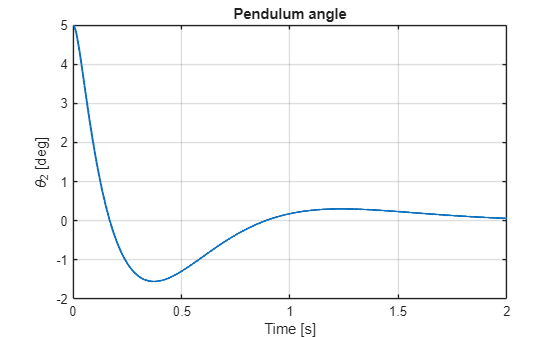


figure;
plot(t, x(:,2)/deg, "LineWidth", 1.5);
grid on;
xlabel("Time [s]");
ylabel("\theta_2 [deg]");
title("Pendulum angle");

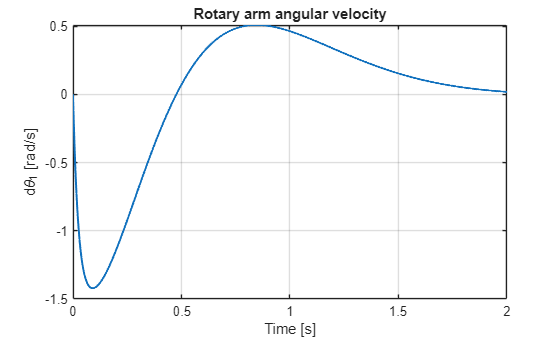


figure;
plot(t, x(:,3), "LineWidth", 1.5);
grid on;
xlabel("Time [s]");
ylabel("d\theta_1 [rad/s]");
title("Rotary arm angular velocity");

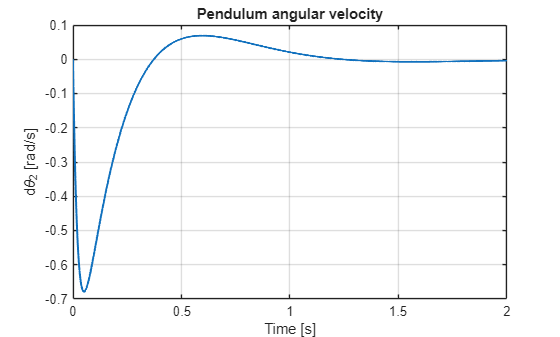


figure;
plot(t, x(:,4), "LineWidth", 1.5);
grid on;
xlabel("Time [s]");
ylabel("d\theta_2 [rad/s]");
title("Pendulum angular velocity");

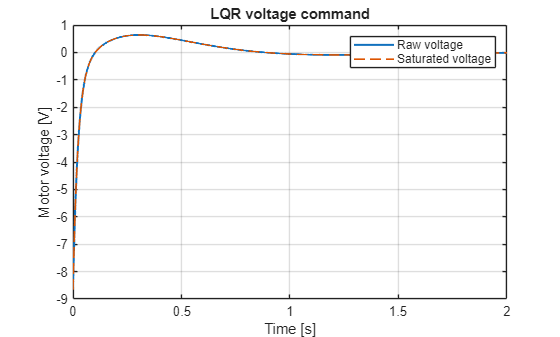



%% 15. Plot voltage input

figure;
plot(t, V, "LineWidth", 1.5);
hold on;
plot(t, V_sat, "--", "LineWidth", 1.2);
grid on;
xlabel("Time [s]");
ylabel("Motor voltage [V]");
title("LQR voltage command");
legend("Raw voltage", "Saturated voltage");

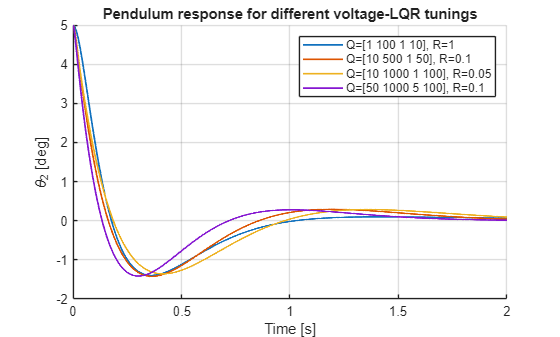



%% 16. Compare several LQR tunings

tunings = [
    1   100   1   10   1;
    10  500   1   50   0.1;
    10  1000  1   100  0.05;
    50  1000  5   100  0.1
];

figure;
hold on;
grid on;
xlabel("Time [s]");
ylabel("\theta_2 [deg]");
title("Pendulum response for different voltage-LQR tunings");

for j = 1:size(tunings,1)

    Q_test = diag(tunings(j,1:4));
    R_test = tunings(j,5);

    K_test = lqr(A_volt, B_volt, Q_test, R_test);
    Acl_test = A_volt - B_volt*K_test;

    sys_test = ss(Acl_test, B_volt, C, D);

    [~,~,x_test] = initial(sys_test, x0, t);

    plot(t, x_test(:,2)/deg, "LineWidth", 1.3, ...
        "DisplayName", ...
        sprintf("Q=[%g %g %g %g], R=%g", ...
        tunings(j,1), tunings(j,2), tunings(j,3), tunings(j,4), tunings(j,5)));
end

legend;



%% 17. Performance values

disp(" ");

disp("====== Performance check ======");

====== Performance check ======



theta2_deg = x(:,2)/deg;

max_theta2 = max(abs(theta2_deg));
max_voltage = max(abs(V));

disp("Max pendulum angle deviation [deg]:");

Max pendulum angle deviation [deg]:


disp(max_theta2);

     5




disp("Max voltage command [V]:");

Max voltage command [V]:


disp(max_voltage);

    8.6605




threshold = 0.5;
settling_time = NaN;

for i = 1:length(t)
    if all(abs(theta2_deg(i:end)) < threshold)
        settling_time = t(i);
        break;
    end
end

disp("Approx. settling time within +/-0.5 deg [s]:");

Approx. settling time within +/-0.5 deg [s]:


disp(settling_time);

    0.7090





%% 18. Real implementation formula

% In real-time code, use:
%
% x = [theta_1;
%      theta_2;
%      dtheta_1;
%      dtheta_2];
%
% V_m = -K*x;
% V_m = max(min(V_m, V_max), V_min);
%
% Then send V_m to the motor driver / analog output.